# Single Heater: Parameter Estimation

**Objective:** Fit the physics-based predictions to the data as well as fit a first-order plus dead-time (FOPDT) model to the data. In both cases, select parameters are adjusted to minimize an objective function such as a sum of squared errors between the model predicted values and the measured values. Test the temperature response of the Arduino device by introducing a step in the heater.

## Gather Data

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);


n = 14 * 60;  % number of seconds to test
time = linspace(0, n, n+1);

% Collect data
filename = 'Step_Response.csv';
absolute_path = fullfile(directory, filename);

% Arrays for Time and Temperature
T1 = zeros(n+1, 1);
tm = zeros(n+1, 1);
% CREATE INTERVALS FOR THE HEATER TO CHANGE
Q1 = zeros(n+1, 1);
Q1(31:4*60) = 70;
Q1(4*60+1:9*60) = 20;
Q1(8*60+1:end) = 45;

try % try to read from file first
    A = readmatrix(absolute_path)
    tm = A(:,1);
    T1 = A(:,2);
    disp('TCLab Data read from file')
    
catch % if file can not be found, simulate
    try 
        % initialize lab
        lab = tclab;
        tic;
        for i=1:n+1
            tm(i) = toc;
            T1(i) = lab.T1;
            lab.Q1(Q1(i));
            figure(1)
            subplot(2,1,1)
            plot(tm(1:i), T1(1:i), 'r.')
            ylabel('Temperature (C)')
            subplot(2,1,2)
            plot(tm(1:i), Q1(1:i), 'r-')
            xlabel('Time (sec)')
            ylabel('Heater Setting (%)')
            pause(1-min(1,toc-tm(i)));
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm T1]
        writematrix(A, absolute_path, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

A =     0.0003715       25.758
       1.8407       25.953
       3.2957       26.002
        4.697       25.904
       6.0936       25.855
        7.472       25.709
       8.8492       25.806
       10.229       25.709
       11.603        25.66
       12.983       25.709


TCLab Data read from file


## **Fit FOPDT Model with Optimization**

Determine the parameters of an FOPDT model that best match the dynamic temperature data including $K_p$, $\tau_p$, and $\theta_p$. A second order (SOPDT) can also be fit to investigate whether a higher order model is more accurate.

x0 = zeros(3,1);
x0(1) = 1; %Km
x0(2) = 120; %taum
x0(3) = 10; %thetam

initial_obj = objective(x0, tm, Q1, T1)

initial_obj =    2.4845e+08


fopdt_params = fminsearch(@(x)objective(x, tm, Q1, T1), x0)

fopdt_params =       0.58331
       128.65
       21.369


optimized_obj = objective(fopdt_params, tm, Q1, T1)

optimized_obj =     2.961e+05


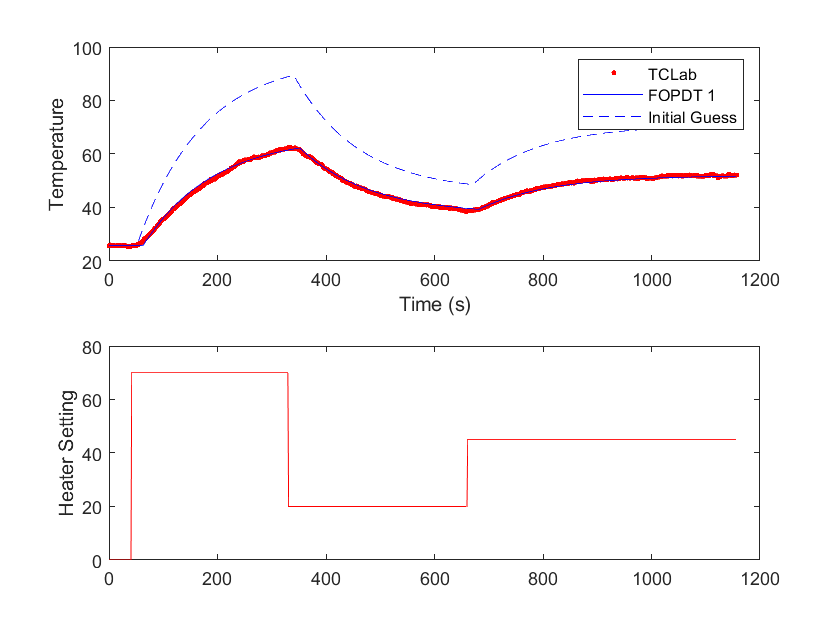


y_i = sim_model(x0, tm, Q1, T1);
y_fopdt = sim_model(fopdt_params,tm, Q1, T1);

figure(2)
subplot(2,1,1)
plot(tm, T1, 'r.')
hold on
plot(tm, y_fopdt, 'b-')
plot(tm, y_i, 'b--')
xlabel('Time (s)')
hold off
legend({'TCLab' 'FOPDT 1' 'Initial Guess' })
ylabel('Temperature')
subplot(2,1,2)
plot(tm, Q1, 'r-')
ylabel('Heater Setting')

## **Fit Physics-Based Model with Optimization**

The full energy balance includes convection and radiation terms.


$$m\,c_p\frac{dT}{dt} = U\,A\,\left(T_\infty-T\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T^4\right) + \alpha Q$$


where $m$ is the mass, $c_p$ is the heat capacity, $T$ is the temperature, $U$ is the heat transfer coefficient, $A$ is the area, $T_\infty$ is the ambient temperature, $ \epsilon=0.9$ is the emissivity, $\sigma$ = 5.67x10-8 $W/{m^2 K^4}$ is the Stefan-Boltzmann constant, and $Q$ is the percentage heater output. The parameter $\alpha$ is a factor that relates heater output (0-100%) to power dissipated by the transistor in Watts.

Adjust the uncertain parameters such as $U$ and $\alpha$ from the modeling exercise to best match the dynamic data from the impulse response.

Here, the function `fmincon `performs constrained optimization subject to the constrain that $Ax \le b$. The coefficients of A and b can be configured to create lower and upper bounds for the regressed values.

u0 = 5;         % U guess
alpha0 = 0.01;  % alpha guess
x0 = [u0, alpha0];


A = [-1,0; ...
    1, 0;...
    0, -1;...
    0, 1;...
    ];
b = [-1; 20; -.0001; 0.05];

initial_obj = objective_energyBalance(x0, tm, Q1, T1)

initial_obj =    1.2959e+07


fopdt_params = fmincon(@(x)objective_energyBalance(x, tm, Q1, T1), x0, A, b)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


fopdt_params =        3.8597    0.0079112


optimized_obj = objective_energyBalance(fopdt_params, tm, Q1, T1)

optimized_obj =    1.3217e+06



y_i = sim_energyBalance(x0, tm, Q1, T1);
y_fopdt = sim_energyBalance(fopdt_params,tm, Q1, T1);

disp('Regressed Heat Transfer Constant (U): '+string(fopdt_params(1)))

Regressed Heat Transfer Constant (U): 3.8597


disp('Regressed Heater Factor (alpha): '+string(fopdt_params(1)))

Regressed Heater Factor (alpha): 3.8597


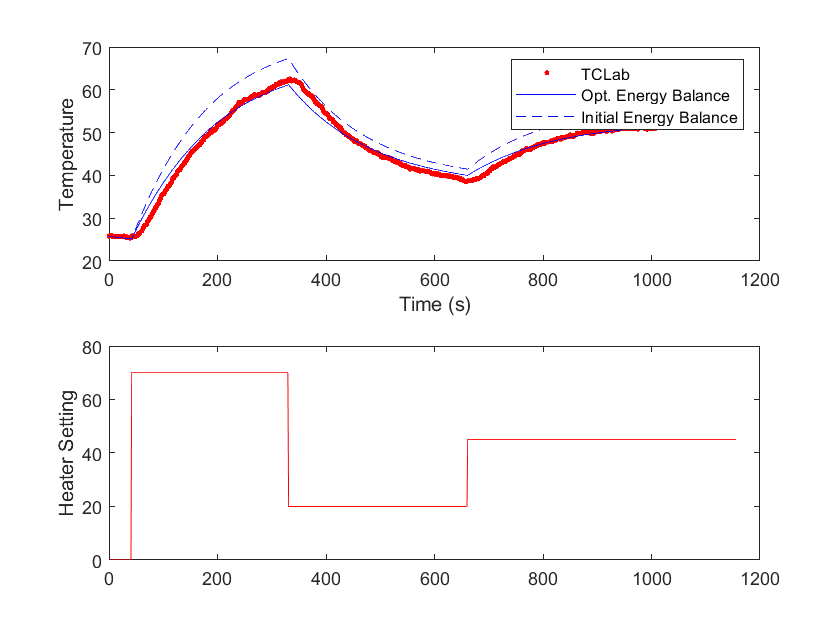


figure(2)
subplot(2,1,1)
plot(tm, T1, 'r.')
hold on
plot(tm, y_fopdt, 'b-')
plot(tm, y_i, 'b--')
xlabel('Time (s)')
hold off
legend({'TCLab' 'Opt. Energy Balance' 'Initial Energy Balance'})
ylabel('Temperature')
subplot(2,1,2)
plot(tm, Q1, 'r-')
ylabel('Heater Setting')

## **Compare FOPDT and Linearized Model**

A linearized version of the model can be used to compare an FOPDT model to the physics-based model. A linearized model is derived as:


$$m\,c_p\frac{dT}{dt} = f\left(T_\infty,T,V\right) \approx f \left(\bar T_\infty, \bar T, \bar V\right) \ldots \\ + \frac{\partial f}{\partial T_\infty}\bigg|_{\bar T_\infty,\bar T,\bar Q} \left(T_\infty-\bar T_\infty\right) \ldots \\ + \frac{\partial f}{\partial T}\bigg|_{\bar T_\infty,\bar T,\bar Q} \left(T-\bar T\right) \ldots \\ + \frac{\partial f}{\partial V}\bigg|_{\bar T_\infty,\bar T,\bar Q} \left(Q-\bar Q\right)$$


where


$$\frac{\partial f}{\partial T_\infty}\bigg|_{\bar T_\infty,\bar T,\bar Q} = U\,A\,\bar T_\infty + 4\epsilon\,\sigma\,A\,\bar T_\infty^3 = \beta$$



$$\frac{\partial f}{\partial T}\bigg|_{\bar T_\infty,\bar T,\bar Q} = -U\,A\,\bar T - 4\epsilon\,\sigma\,A\,\bar T^3 = \gamma$$



$$\frac{\partial f}{\partial Q}\bigg|_{\bar T_\infty,\bar T,\bar Q} = \alpha$$


The final linearized equation is further simplified by replacing the partial derivatives with constants $\beta$, $\gamma$, and $\alpha$ that are evaluated at the steady state conditions $\bar T_\infty$, $\bar T$, and $\bar Q$.


$$m\,c_p\frac{dT}{dt} = \beta \left(T_\infty-\bar T_\infty\right) + \gamma \left(T-\bar T\right) + \alpha \left(Q-\bar Q\right)$$


This is placed into a time-constant form as by dividing by gamma and substituting the deviation variables $T\prime_\infty = T_\infty -\bar T_\infty$, $T\prime = T -\bar T$, and $Q\prime = Q -\bar Q$.


$$\frac{m\,c_p}{\gamma}\frac{dT^\prime}{dt} = \frac{\beta}{\gamma} T^\prime_\infty + T^\prime + \frac{\alpha}{\gamma} Q^\prime$$


Further simplification is possible with $\beta = -\gamma$.


$$\frac{m\,c_p}{\gamma}\frac{dT^\prime}{dt} = -T^\prime_\infty + T^\prime + \frac{\alpha}{\gamma} Q^\prime$$


Multiplying both sides by *-1* puts the equation into a time constant form with new constants $\tau_P$ and $K_p$.


$$\tau_P \frac{dT^\prime}{dt} = -T^\prime + T^\prime_\infty + K_p Q^\prime$$



$$K_P = -\frac{\alpha}{\gamma}$$



$$\tau_P = -\frac{m\,c_p}{\gamma}$$


This derivation does not include a time delay but the other parameters can be correlated to an empirical FOPDT fit of the data. Another way to fit the uncertain parameters such as overall heat transfer coefficient and $\alpha$ is to use optimization methods. There is a script that demonstrates the use of optimization to minimize an objective function. The objective function is a minimization of the difference between the predicted and measured values.

## **Moving Horizon Estimation**

Sometimes parameters may change over the course of a simulation or control. Moving Horizon Estimation involves real-time regression of unknown parameters while controling a process. Recent data within a specified window is used to regress parameters. Then, the process is controlled based on a model including the regressed parameters.

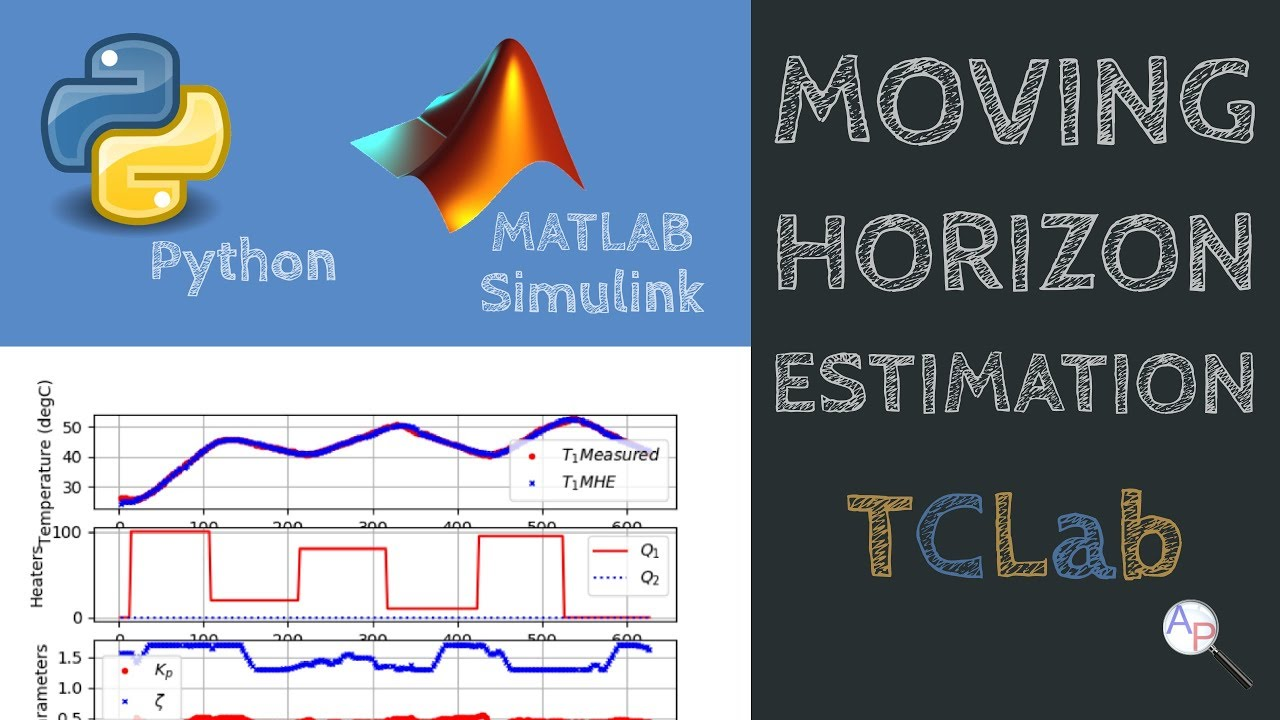

### [View Lecture](https://www.youtube.com/watch?v=Cp6fPUptc74)

function dydt = fopdt(t, y, u, tvals, Km,taum,thetam, yp1, u1)
    % arguments
    %  t      = time
    %  y      = output
    %  Km     = model gain
    %  taum   = model time constant
    %  thetam = model dead time constant
    %  yp1    = initial output value
    %  u1     = initial input value

    try
        if (t-thetam) <= 0
            um = u1;
        else
            um = interp1(tvals, u, t-thetam);
        end
    catch 
        disp('Error with time extrapolation: ' + t )

        um = u1;
    end
    % calculate derivative
    dydt = (-(y-yp1) + Km * (um-u1))/taum;
end

% simulate FOPDT model with x=[Km,taum,thetam]
function ym = sim_model(x, time_, u_, yp_)
    % input arguments
    Km = x(1);
    taum = x(2);
    thetam = x(3);
    
    ns = length(time_);
    yp1 = yp_(1);
    u1 = u_(1);
    
    % storage for model values
    ym = zeros(ns, 1);  % model
    % initial condition
    ym(1) = yp1;
    % loop through time steps    
    for i = 1:ns-1
        ts = [time_(i),time_(i+1)];
        [~, ys] = ode45(@(t, y) fopdt(t, y, u_, time_, Km,taum,thetam, yp1, u1), ts, ym(i));
        ym(i+1) = ys(end);
    end
end

function obj = objective(x_arg, time_, u_, yProcess)
    % simulate model
    ym = sim_model(x_arg, time_, u_, yProcess); 
    % calculate objective with sum squared error
    obj = sum((ym-yProcess).^2)*1000;
end

function dTdt = heat(~, T, Q, params)
    % unpack unknown parameters
    U = params(1);
    alpha = params(2);
    
    % known parameters
    m = 0.004;  % Kg
    Cp = 500;  % J/kg k
    A = 1.2e-3;  % m^2
    eps = 0.9;
    sigma = 5.67e-8;  % Steffan Boltzman constant
    Ta = 23;
    Tk = T + 273.15;
    Tak = Ta + 273.15; 
    
    dTdt = (1.0/(m*Cp))*(U*A*(Ta-T) ...
                + eps * sigma * A * (Tak^4 - Tk^4) ...
                + alpha*Q);
end

function T_ = sim_energyBalance(params, time_, u_, yp_)

    ns = length(time_);
    
    % storage for model values
    T_ = ones(ns, 1) * 23.0;  % model
    % initial condition
    T_(1) = yp_(1);
    % loop through time steps    
    for i = 1:ns-1
        ts = [time_(i),time_(i+1)];
        [~, ys] = ode45(@(t, y) heat(t, y, u_(i), params), ts, T_(i));
        T_(i+1) = ys(end);
    end
end

function obj = objective_energyBalance(params, time_, u_, yProcess)
    % simulate model
    ym = sim_energyBalance(params, time_, u_, yProcess); 
    % calculate objective with sum squared error
    obj = sum((ym-yProcess).^2)*1000;
end